# **Problem 3:**

clc;
clear all;
dt0=1e-8;
t_0=0+dt0:dt0:10e-3;
N=length(t_0);
Y_f=zeros(1,N);
for i=1:N
    Y_f(i) = findY(t_0(i));
end

## **Problem 3_a:**

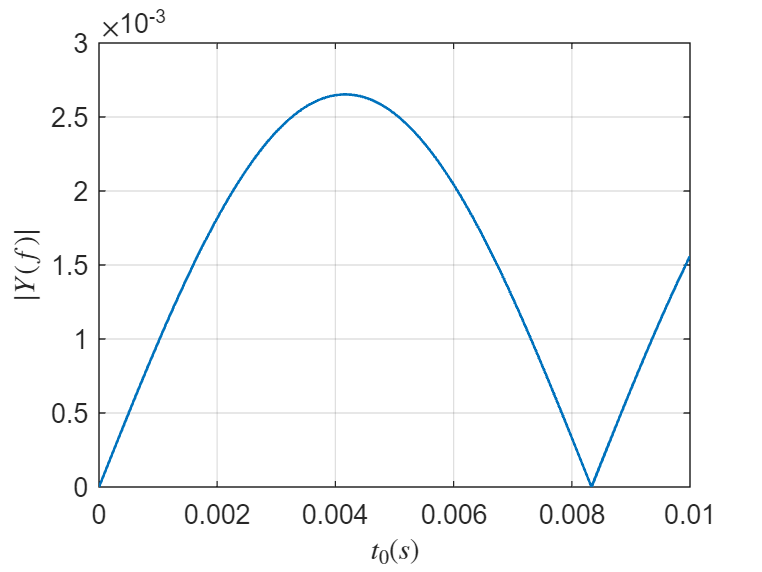

absY_f=abs(Y_f);
figure(1)
plot ( t_0,absY_f,'LineWidth',1);
ylabel('$|Y (f)|$','FontWeight','bold','Interpreter','latex');
xlabel('$t_0 (s)$','FontWeight','bold','Interpreter','latex');
grid on;

## **Problem 3_b:**

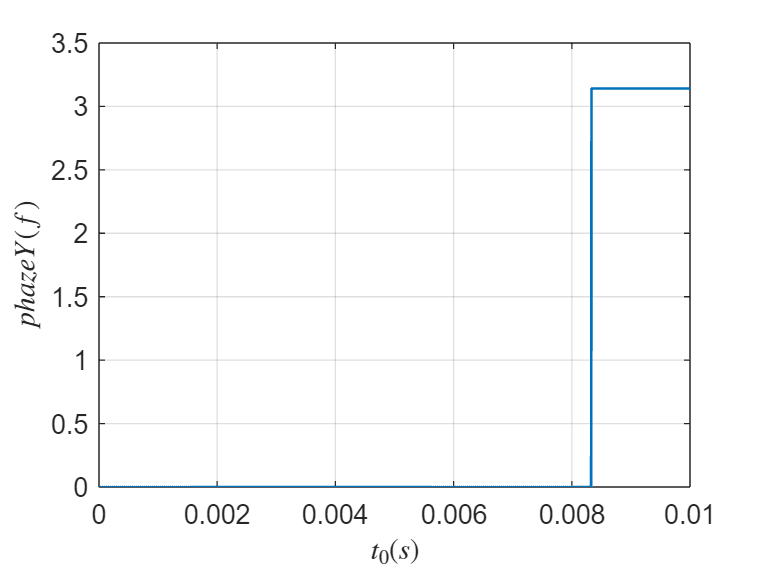

phY_f = angle(Y_f);
figure(2)
plot ( t_0,phY_f,'LineWidth',1);
ylabel('$phaze Y (f)$','FontWeight','bold','Interpreter','latex');
xlabel('$t_0 (s)$','FontWeight','bold','Interpreter','latex');
grid on;

function output = TheSinc(t)
    if t==0
        output=1;
    else
        output=sin(pi*t)/(pi*t);
    end
end
function Y=findY(t0)
    Y=0.5*t0*((TheSinc(60*t0)*exp(-j*pi*60*t0))+(TheSinc(-60*t0)*exp(j*pi*60*t0)));
end